# Simulating a multi-level dataset for linear mixed effects analysis

This tutorial takes a simulation-based approach to understanding mixed effects models.  We start with the fundamental equations specifying the model structure. Then, we simulate data with two variance components and fit several mixed effects models to it.

Why do we do this?  Even the most advanced users do not necessarily know the implications and effects of the assumptions and procedures used in modeling. A simulation-based approach allows you to interrogate how the model performs under different scenarios (i.e., data and experimental design conditions). This provides a way of understanding the models' behavior, including **bias**, **variance**, **power**, and **false positive rates**.

[This video](https://youtu.be/OL6UezgpmPo?list=PLB2iAtgpI4YEAUiEQ1ZnfMXY-yewNzn9z) on simulating mixed effects data by Jeanette Mumford is a clear and gentle introduction that might be helpful. It is part of the [Mumford mixed effects models series on Youtube](https://www.youtube.com/playlist?list=PLB2iAtgpI4YEAUiEQ1ZnfMXY-yewNzn9z).  She also has a [Mumford mixed models in fMRI series](https://www.youtube.com/playlist?list=PLB2iAtgpI4YFbAR9D4ZmWohRFXB3w5DWK).

## **Model formulation**

**First level:** 


$$Y=Z_i\beta_i+\epsilon_i$$


This describes how individual-participant data are generated from a set of fixed predictors and participant-specific model parameters ("true" regression intercept and slope values for each participant). Outcome data vector $y\;$for participant $i$($y_i$) is generated by a within-person design matrix $Z_i$times participant-specific coefficient vector $\beta_i$ plus participant specific error vector $\epsilon_i$. 

-  $i=\left\lbrace 1\ldotp \ldotp \ldotp m\right\rbrace$, where $m$is the number of participants. 

- $y$ and $\epsilon_i$ are $n_i \;x\;1$vectors corresponding to $n_i$ observations

- $Z_i$is an $n_i \;x\;p\;$**within-person design matrix** of $p\;$model predictors (regressors). $Z_i$ can vary across participants. $p$ has the same value for all participants. One column of $Z_i \;$is constant across all rows, and its coefficient reflects the model intercept.

- $\beta_i$ is a $p\;x\;1\;$vector of participant-specific model parameters. Note that these are theoretical values, not estimates, as we are laying out the structure of the model. These are **fixed effects, **population-level effects of predictors that we are trying to estimate. 

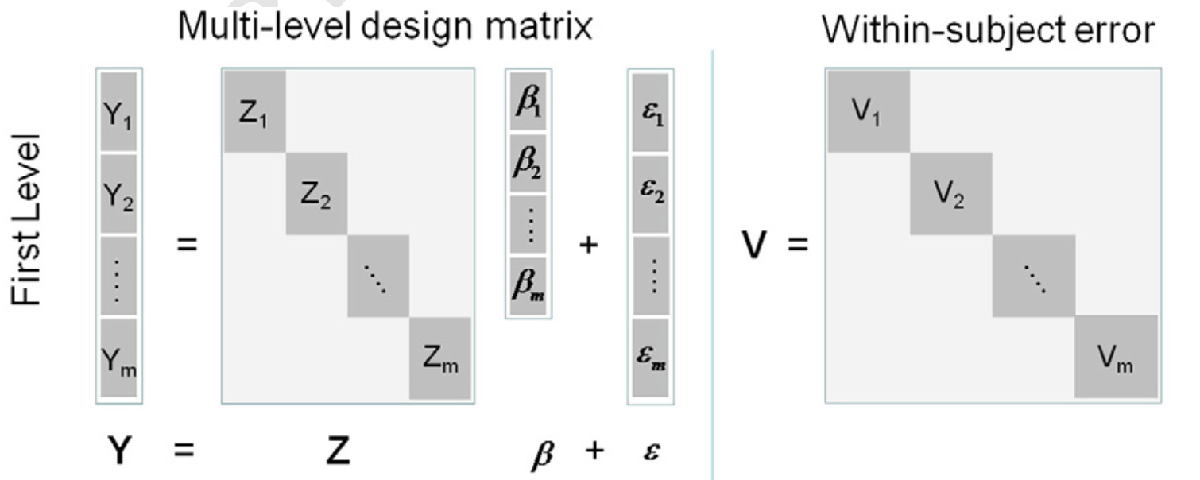

Note that $Z_i$ is *block diagonal* here.  

**Second level**:


$$\beta_i =A\beta_G +\eta_i$$


This describes how participant-specific model parameters $\beta_i$ are generated from between-person (**g**roup-level) population-level model parameters $\beta_G$. $\beta_i$ is generated by a between-person design matrix $X_G$ (see below) times fixed population-level coefficient vector $\beta_G$ plus participant-specific deviation $\eta_i$. 

- $\beta_i$ is a $p\;x\;1\;$vector of participant-specific model parameters.

- $\beta_P$ is a $p\;x\;1\;$vector of fixed population-level model parameters.

- *A* is a placeholder identity matrix for group-level variables here, *eye(p)*

- $\eta_i$is a participant-specific deviation from population-level effects.  If participants are selected randomly from a population, $\eta_i$ varies randomly across $m$ levels, and introduces a **random effect**. 

**Combined two-level model **


$$\begin{array}{l}
Y_i =Z_i \left({\mathrm{X}}_G \beta_G +\eta_i \right)+\epsilon_i \;\\
Y_i =Z_i {\mathrm{X}}_G \beta_G +Z_i \eta_i +\epsilon_i 
\end{array}$$


$X_G$ is an $\textrm{mp}\;x\;p\;$**second-level** **design matrix** of between-person predictors for the intercept and other model parameters.  

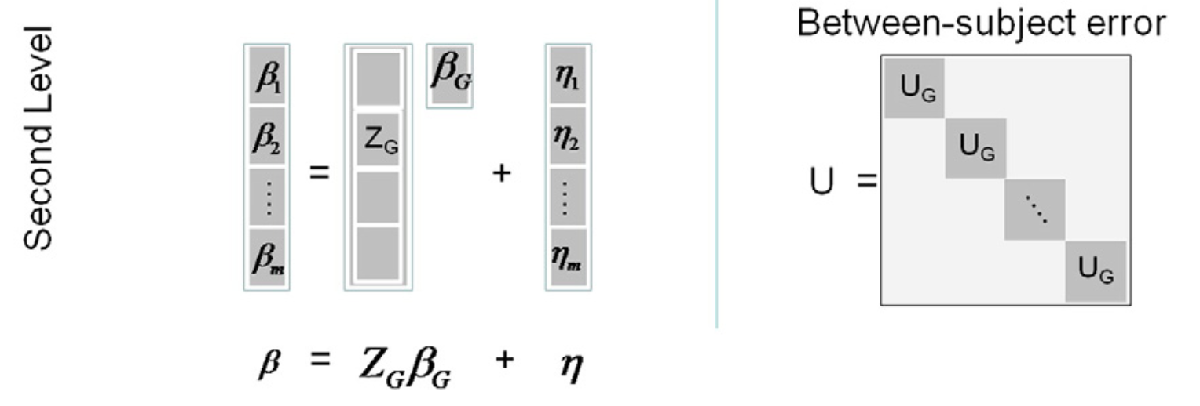

**Alternative notations**

There are several other notation systems that differ somewhat in the notation used. Here are the equations used in the Mumford video lectures.

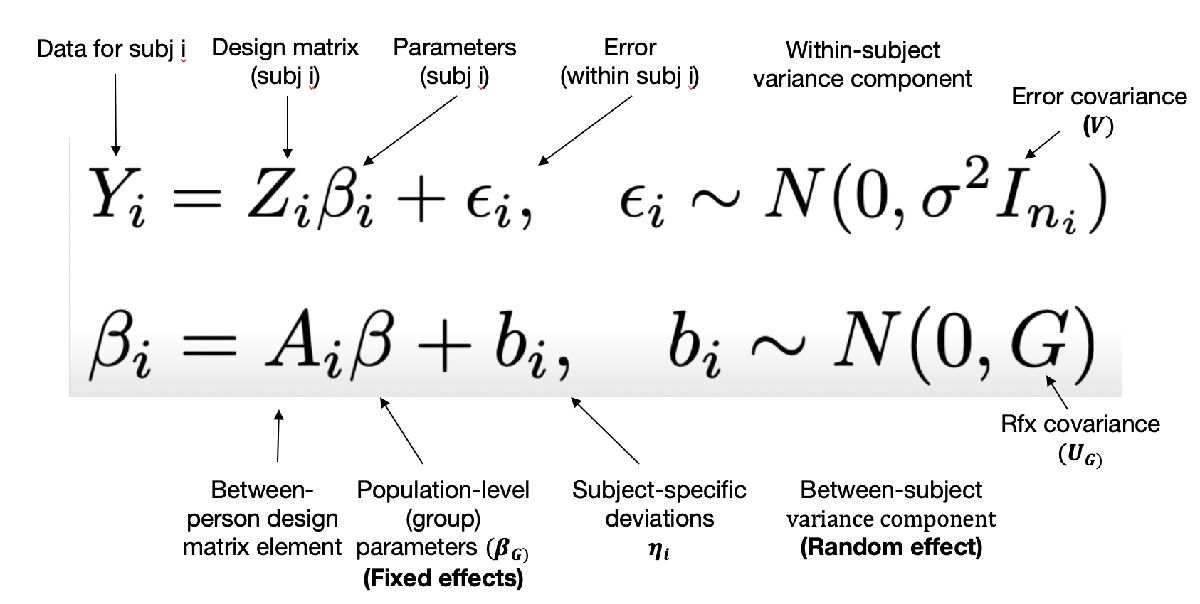

## A simple example

Let's generate some data with made-up slopes. We have a simple model with a linear predictor and an intercept for each person.


disp('Design matrix');

Design matrix


Zi = [1 1 1 1 1; 0 1 2 3 4]'

Zi =      1     0
     1     1
     1     2
     1     3
     1     4



disp('Number of subjects')

Number of subjects


m = 3

m = 3


disp('Number of observations within-person, and num predictors')

Number of observations within-person, and num predictors


[n_within, p] = size(Zi)

n_within = 5

p = 2


disp('Z is the Kronecker product of an [m x m] identity matrix and Zi');

Z is the Kronecker product of an [m x m] identity matrix and Zi


disp('The Kronecker product expands Zi into a block diagonal matrix for every subject.');

The Kronecker product expands Zi into a block diagonal matrix for every subject.



Z = kron(eye(m), Zi)

Z =      1     0     0     0     0     0
     1     1     0     0     0     0
     1     2     0     0     0     0
     1     3     0     0     0     0
     1     4     0     0     0     0
     0     0     1     0     0     0
     0     0     1     1     0     0
     0     0     1     2     0     0
     0     0     1     3     0     0
     0     0     1     4     0     0



disp('Made-up true betas')

Made-up true betas


disp('Intercept and slope for each of m persons, concatenated')

Intercept and slope for each of m persons, concatenated


beta = [0 2 1 3 4 6]'

beta =      0
     2
     1
     3
     4
     6



disp('True response');

True response


y = Z*beta  % Now each person's fit is a combination of their individual Zi and beta_i

y =      0
     2
     4
     6
     8
     1
     4
     7
    10
    13



% Plot the true response without error
ycell = mat2cell(y, n_within * ones(m, 1))';
x1 = repmat({Zi(:, 2)}, 1, m);
create_figure('example'); 
handles = line_plot_multisubject(x1, ycell);

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.68 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, subject is random effect: 
Mean b = 3.67, t(  2) = 3.05, p = 0.092735, num. missing:   0   
                                                                
Average within-person r = 1.00 +- 0.00 (std)
 
Between-person r (across subject means) = NaN, p = NaN
_________________________________________________________________________________________________________________________________________

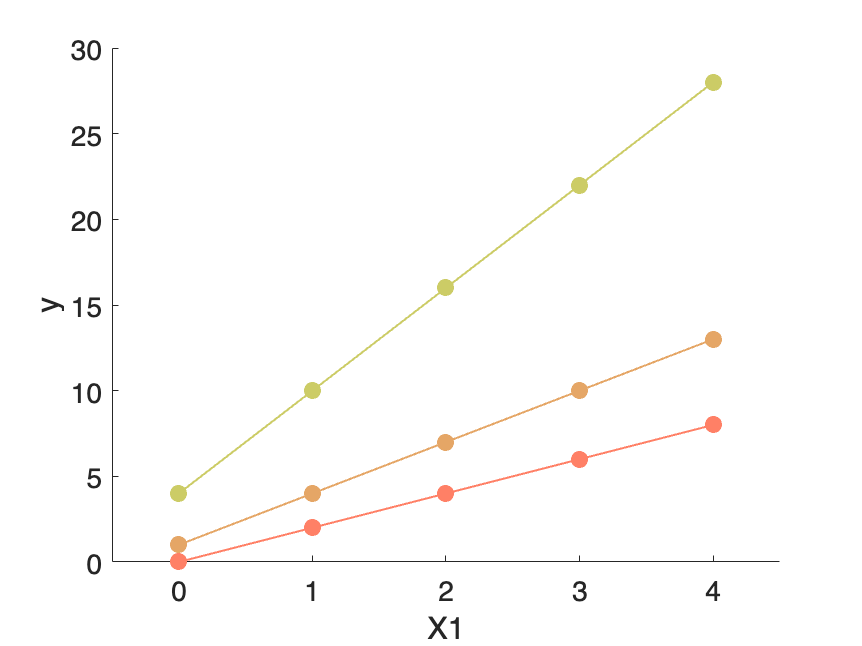

set(handles.point_handles, 'MarkerSize', 8, 'Marker', 'o'); % we can use handles to reformat things
set(gca, 'XLim', [-0.5 4.5])
xlabel('X1'); ylabel('y');

The response (y) will also be measured witih error.  Let's add some errors.

Here, the errors are normally distributed with var = 1. Here the errors are homoscedastic across subjects.

This is a common assumption in mixed effects models, e.g., lmer in R, but not all models make this assumption.

e = randn(size(y, 1), 1);

y = y + e;

% Plot the true response with error
ycell = mat2cell(y, n_within * ones(m, 1))';
x1 = repmat({Zi(:, 2)}, 1, m);
create_figure('example'); 
handles = line_plot_multisubject(x1, ycell);

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.66 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, subject is random effect: 
Mean b = 3.53, t(  2) = 2.67, p = 0.115979, num. missing:   0   
                                                                
Average within-person r = 0.98 +- 0.03 (std)
 
Between-person r (across subject means) = NaN, p = NaN
_________________________________________________________________________________________________________________________________________

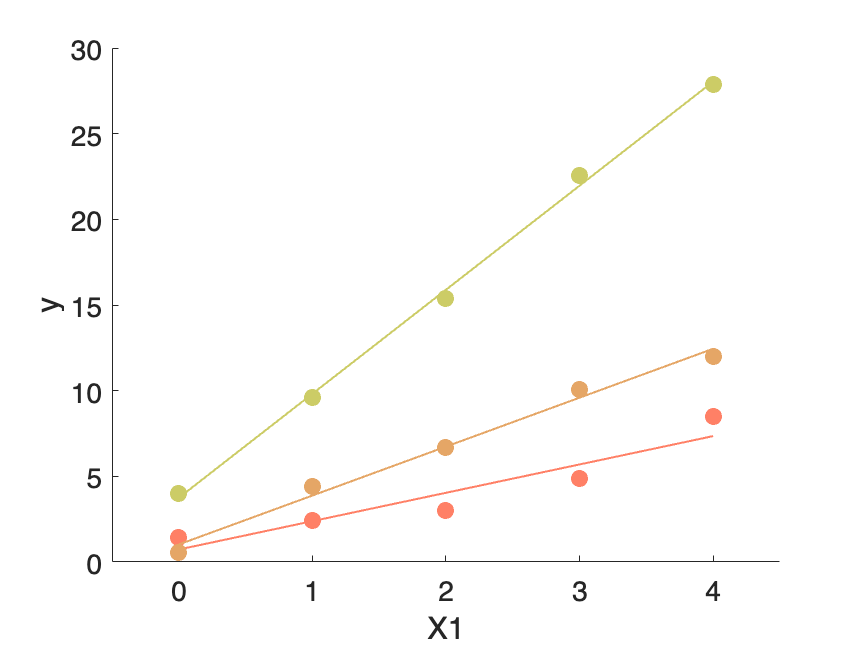

set(handles.point_handles, 'MarkerSize', 8, 'Marker', 'o'); % we can use handles to reformat things
set(gca, 'XLim', [-0.5 4.5])
xlabel('X1'); ylabel('y');

The variation in betas 1, 3, and 5 reflects individual differences in the intercept.

The variation in betas 2, 4, and 6 reflects individual differences in the slope of X1.

We set these to fixed values above, but in the next section, these individual differences will be randomly selected from a distribution.  The "true" individual differences among subjects are thus **random effects**.

## A more flexible simulation

### Specify parameters and model structure


% number of subjects
m = 20;         

% n observations within-subject
% For now, assume same across all subjects

n_within =20; 

n_i = n_within * ones(m, 1); 

% Number of model parameters (regressors), including intercept
p = 2;

% Within-person residual noise variance
% For now, assume same across all subjects
sig_2_within =1.1;

% s2 is 1 x m vector of residual variances
s2 = sig_2_within .* ones(1, m);

**Fixed population-level effects**

Specify a column vector of true population-level values for each effect, intercept followed by other parameters.

b_g = [5 2]';

% Check the size 
if any(size(b_g) - [p 1])
    error('Population effects b_g is the wrong size')
end

**Group-level covariance matrix**

Diagonals are variances for each of p parameters. By convention, the intercept is first. 

Off-diagonals are covariances

e.g., for an intercept and slope (simple multilevel regression), U_g would be a 2 x 2 matrix with variances of the intercept and slope on the diagonal.


U_g = [20 0; 0 10];  

% Check the size 
if ~all(size(U_g) == p)
    error('Covariance matrix U_g is the wrong size')
end

%%

**Fixed design matrix**

These can be the same for all subjects, or different. They'd be the same if we were using a fixed experimental design with the same numbers of observations per person, and different if (1) our predictors are measured variables or (2) we have different numbers of observations. 

We'll assume they are the same across participants for now, but allow the code to be easily extended to different design matrices across participants.

Predictors can also be categorical or continuous, and correlated or uncorrelated. We'll generate a simple effects-coded [1 -1] predictor for now, with approximately balanced numbers of observations.

The intercept is first (a column of 1's) by convention.

Z_within = [ones(n_within, 1)]; % intercept

Z_tmp = randn(n_within, p - 1); 

Z_tmp(Z_tmp >= 0) = 1;
Z_tmp(Z_tmp <= 0) = -1;

Z_within = [Z_within Z_tmp];

Z_i = {};
for i = 1:m         % allows subjects to vary later if needed

    Z_i{i} = Z_within;

end


Now we have all the variables we need to simulate data:

n_i                         Number of observations for each person i = 1...m

b_g                        Population-level true fixed effects parameters 

s2                          residual variances for each person (1 x m)

U_g                        Group covariance matrix

Z_i                         Design matrix for each person

#### Questions to answer

Under most input parameter choices, the dataset will include a random subject intercept and random subject slope. 

Which input parameter would you change to make the dataset consistent with a "random intercept only" model?

Which input parameter would you change to make the dataset consistent with a "random slope only" model?

### **Create simulated dataset**

**Generate subject-level true parameters**

Assume a normal distribution with covariance  U_g

beta_i here is an [p x m] matrix where column i is the [p x 1] true beta coefficient vector for subject i.

beta_i = mvnrnd(b_g, U_g, m)';

**Generate data (y)**

y = cell(1, m);

for i = 1:m         

    y{i} = Z_i{i} * beta_i(:, i) + sqrt(s2(i)) .* randn(n_i(i), 1);

end

To fit the dataset, we'll need these variables:

y{i = 1...m}            The DV/outcome

Z_i{i = 1...m}         The design matrix for each person

CANlab functions like **glmfit_multilevel**, **igls**, and **rigls** can use these cell arrays directly.

For **fitlm** and **fitlme**, and **lmer** in R (etc.), we will want these in stacked, 'long format' tabular form for mixed effects models.  This requires a Grouping (in this case a Subject ID variable) as well. We will also create a column for each predictor and leave out the intercept, as it's added automatically.

% Make a long-format table with simulated data

sim_data = table(cat(1, y{:}), 'VariableNames', {'Y'});

sid_tmp = {}; % Subject ID
var_tmp = {}; % predictor variables

for i = 1:m         

    % Subject ID
    sid_tmp{i} = i .* Z_i{i}(:, 1);  % use intercept in case n's vary

    for j = 1:(p-1)

        var_tmp{j}{i} = Z_i{i}(:, j+1); 

    end

end

sim_data.sid = cat(1, sid_tmp{:});

% add other variables
for j = 1:(p-1)

    varname = sprintf('x%02d', j);
    sim_data.(varname) = cat(1, var_tmp{j}{:});

end

sim_data

sim_data = 400×3 table
       Y       sid    x01
    _______    ___    ___

     -4.032     1      1 
    -3.8698     1      1 
    -4.0851     1     -1 
    -3.9542     1      1 
     -3.804     1     -1 
     0.1725     1     -1 
    -2.8657     1     -1 
    -2.5798     1     -1 
    -2.6348     1     -1 
    0.57301     1     -1 
    -3.2829     1     -1 
    -3.1335     1     -1 
    -3.4389     1     -1 
    -4.9082     1      1 
    -2.4587     1     -1 
    -3.7196     1     -1 


### Plot the dataset

For plotting, we may need to extract a predictor. This extracts the first non-intercept predictor (if p > 1 and there is one).

We'll use the CANlab function **line_plot_multisubject. **It gives us some output and basic stats on the relationship between x1 and y as well.

ans =   Figure (multisubject data) with properties:

      Number: 2
        Name: 'multisubject data'
       Color: [1 1 1]
    Position: [584 595 560 420]
       Units: 'pixels'

  Show all properties


line_plot_multisubject output:


Warnings:

____________________________________________________________________________________________________________________________________________
Y: input cells with low varability:
3
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.47 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, subject is random effect: 
Mean b = 3.54, t( 19) = 4.27, p = 0.0

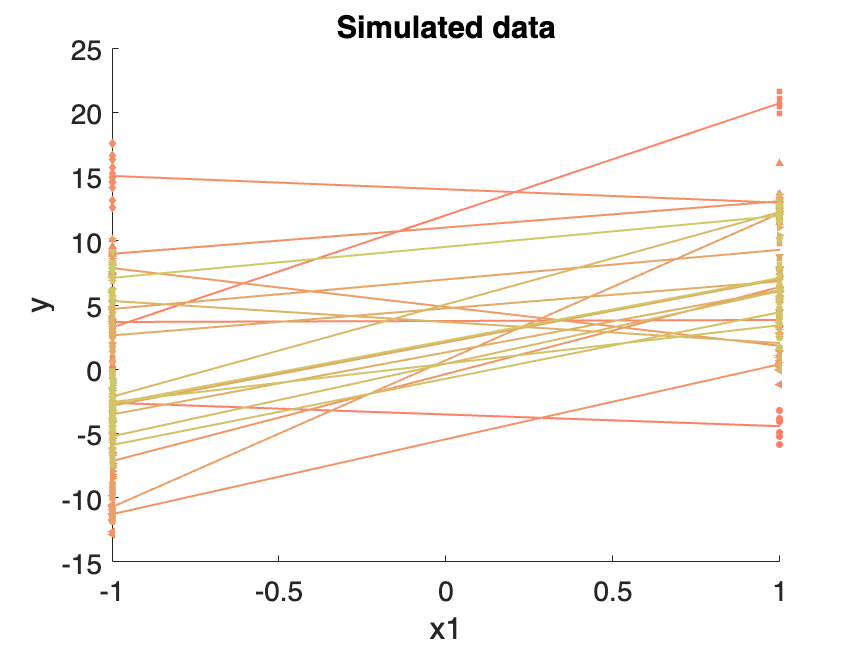

if p > 1
    x1 = cellfun(@(x) x(:, 2), Z_i, 'UniformOutput', false);

    create_figure('multisubject data')
    disp('line_plot_multisubject output:')
    [han, ~, ~, slope_stats] = line_plot_multisubject(x1, y);

    xlabel('x1')
    ylabel('y')
    title('Simulated data')

else
    disp('Intercept only: No x1-y relationship to plot')
end

### Fit the model

#### **glmfit_multilevel**

**glmfit_multilevel** is a CANlab function. It is a fast and simple option for running a two-level mixed effects model with participant as a random effect. It implements a random-intercept, random-slope model across 2nd-level units (e.g., participants). it fits regressions for individual 2nd-level units (e.g., participants), and then (optionally) uses a precision-weighted least squares approach to model group effects (if the 'weighted' keyword is entered). It thus treats participants as a random effect. This is appropriate when 2nd-level units are participants and 1st-level units are observations (e.g., trials) within participants. glmfit_multilevel was designed with this use case in mind.

Options:

glmfit_multilevel includes some options that are not included in many

mixed effects models, including **bootstrapping** or **sign permutation** for inference

Inputs:

- y = cell array, one cell per subject.  Each cell contains a column vector of  outcome data for that subject, across lower-level observations (e.g., trials).

- x1 = cell array, one cell per subject.  Each cell contains a [trials x predictors] matrix of  predictor data for that subject.

disp('glmfit_multilevel output:')

glmfit_multilevel output:



stats = glmfit_multilevel(y, x1, [], 'verbose');

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  20, Predictors:   1
Outcome names: 1st-level B1	1st-level B2	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.00 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	1st-level B1	1st-level B2	
Adj. mean	3.64	3.54	

2nd-level B01
	1st-level B1	1st-level B2	
Coeff	3.64	3.54	
STE	1.14	0.83	
t	3.20	4.27	
Z	2.83	3.53	
p	0.00469	0.00041	

________________________________________


#### fitlme

This is Matlab's object-oriented equivalent to lmer in R. It fits a variety of mixed effects models. A list of methods and properties are here:

These models, like many other statistics objects implementing linear models, allow you to specify model formulas using [Wilkinson notation](https://www.mathworks.com/help/stats/wilkinson-notation.html). There is also a matrix input version.

help LinearMixedModel

 LinearMixedModel Fitted linear mixed effects model.
    LME = FITLME(...) fits a linear mixed effects model to data. The fitted
    model LME is a LinearMixedModel modeling a response variable as a
    linear function of fixed effect predictors and random effect
    predictors.
 
    LinearMixedModel methods:
        coefCI - Coefficient confidence intervals
        coefTest - Linear hypothesis test on coefficients
        predict - Compute predicted values given predictor values
        random - Generate random response values given predictor values
        partialDependence - Partial Dependence value


disp('fitlme output:')

fitlme output:



lme = fitlme(sim_data,'Y ~ x01 + (1 + x01|sid)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             400
    Fixed effects coefficients           2
    Random effects coefficients         40
    Covariance parameters                4

Formula:
    Y ~ 1 + x01 + (1 + x01 | sid)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    1433.1    1457    -710.54          1421.1  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat     DF     pValue        Lower     Upper 
    {'(Intercept)'}        3.6373       1.1069    3.2859    398     0.0011066    1.4611    5.8135
    {'x01'        }        3.5392      0.80765    4.3821    398    1.5057e-05    1.9514     5.127

Random effects covariance parameters (95% CIs):
Group: sid (20 Levels)
    Name1                  Name2                  Type            Estimate    Lower       Upper


anova(lme, 'DFMethod', 'Satterthwaite')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        10.797    1      20      0.0036938
    {'x01'        }        19.203    1      20     0.00028801


pval = coefTest(lme,[1 0]);

#### igls / rigls

disp('igls output:')

igls output:


MST (diag of Ystar_mtx): 40.85556
MSE (diag of resid): 0.00000


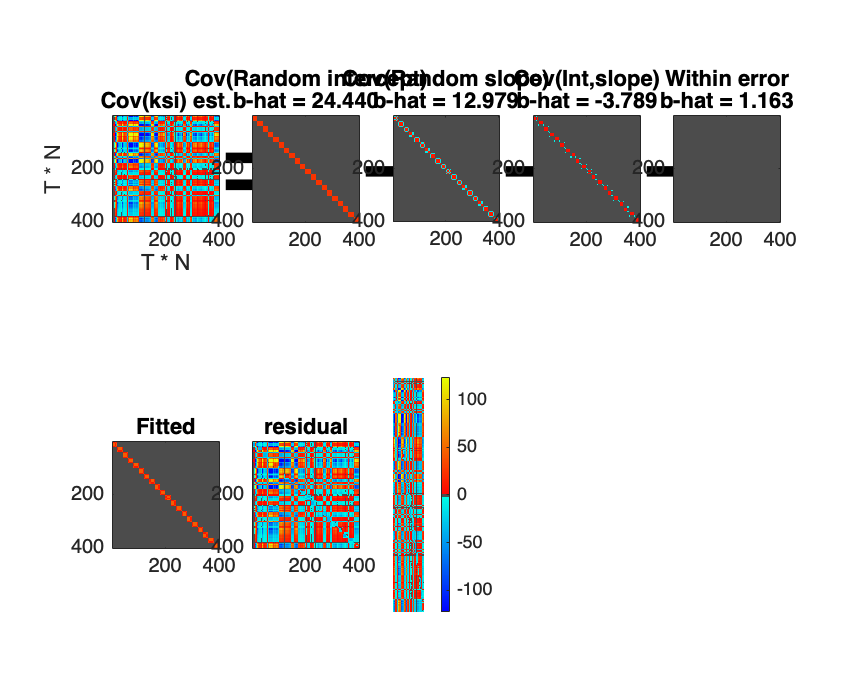

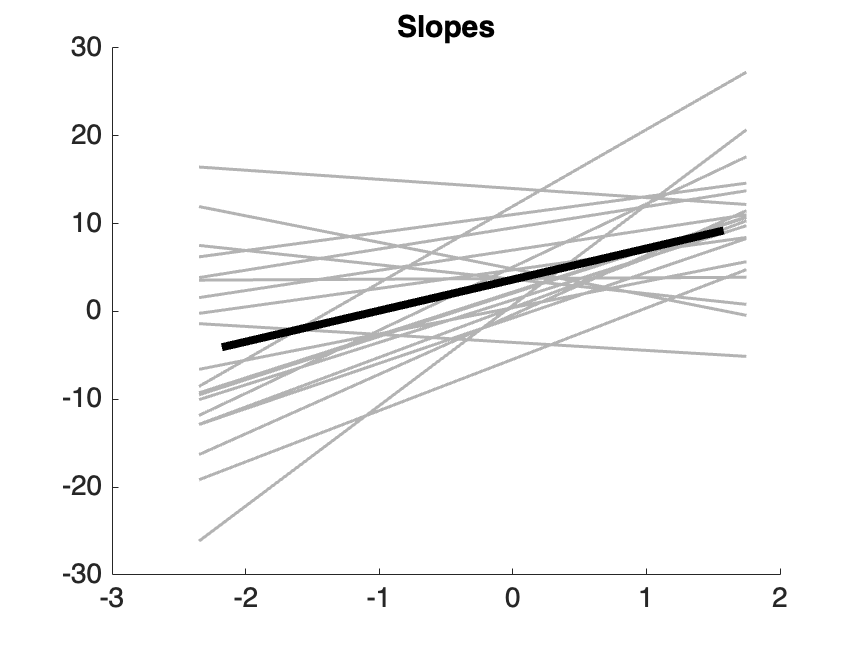


igls.m output report:
---------------------------------------
Data:  20 observations x  20 subjects 
Fit Type: igls
AR(p) model: No
Converged: Yes
Max iterations:   5, Completed iterations:   1
Epsilon for convergence: 0.010000
Elapsed time: 0.32 s

Statistics: Tests of inference on fixed population parameters
Parameter	est.	t( 19)	p	
Intcpt.	3.637	3.29	0.003885	**
Slope1	3.539	4.38	0.000320	***


Statistics: Tests of significance on random effects (variances)
Parameter	est.	LRT	p	
Intcpt.	24.440	1047.88	0.000000	***
Slope1	12.979	832.30	0.000000	***

---------------------------------------




 igls_stats = igls(y, x1, 'plot', 'all');

 disp('Est.  random-effect variances: '); disp(sqrt(igls_stats.betastar)');

Est.  random-effect variances: 
    4.9436    3.6026





 disp('Estimated fixed effects')

Estimated fixed effects


 igls_stats.beta

ans =     3.6373
    3.5392



 disp('True fixed effects')

True fixed effects


 b_g

b_g =      5
     2



 disp('Estimated random effects (covariances)')

Estimated random effects (covariances)


 igls_stats.betastar

ans =    24.4395
   12.9790



 disp('True random effects (covariances)')

True random effects (covariances)


 diag(U_g)

ans =     20
    10


### Hands-on Activities

- Identify and compare residual variance terms, slope estimates, t-values across models

- Modify the code to generate one or more continuous predictors instead of categorical/experimental ones.

- Turn the data-generation script into a function, so that you can efficiently simulate **power** and **false positive rates** using repeated simualtions -- two key properties of any statistical model.

A Matlab version is included in the function *sim_generate_mixedfx_data1, *which is called below.  You can create your own version in the software package of your choice (e.g., Python, R).


regressortype = 'categorical';

[y, Z_i, x1, sim_data] = sim_generate_mixedfx_data1(m, n_i, p, b_g, s2, U_g, regressortype);

sim_data

sim_data = 400×3 table
       Y       sid    x01
    _______    ___    ___

     7.1248     1      1 
      2.894     1     -1 
     4.7317     1     -1 
     4.0255     1     -1 
     3.7738     1     -1 
     2.7529     1     -1 
     3.6547     1     -1 
     2.1745     1     -1 
     4.8593     1      1 
     6.9221     1      1 
     6.6253     1      1 
     3.8653     1     -1 
     7.6663     1      1 
     5.2197     1      1 
    0.26276     1     -1 
     3.5789     1     -1 


## Extended simulations

With a bit more extension, these simulations can be used to answer a number of questions. 

- Simulate data in R and fit using LMER. Compare/contrast output and create a "cheat sheet" comparing output

- Compare TPR and FPR across methods - matlab, R, glmfit_multilevel

- Compare with RM ANOVA

- Simulate and compare true positive rates (TPR, power) and  false positive rates (FPR) in these interesting cases:

-     mismodeling: ignoring a random effect  

-     unbalanced data across levels of a predictor

-     unequal N within subject

-     unequal variances within-subject

-     experimental design vs. normally-distributed predictors

-     non-normally distributed errors

-     more vs. fewer irrelevant predictors 

-     more levels of a predictor (mixed vs ANOVA)

-     crossed random effects with more or fewer levels